load('net.mat')
load('test_data_lorenz_cell2.mat');


netLorenz = net;

% Setting up simulation parameters
start = 1;
numSimulations = 20;
test_data_lorenz = test_data_lorenz_cell2;


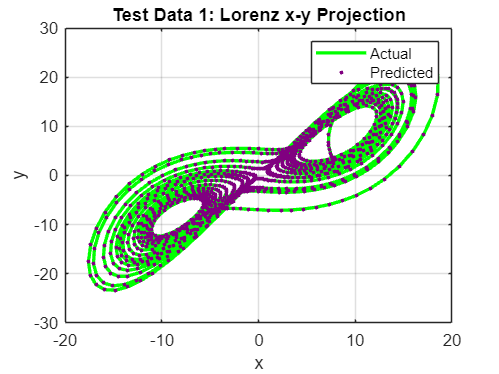

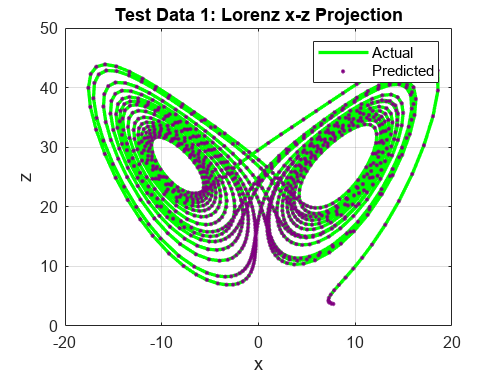

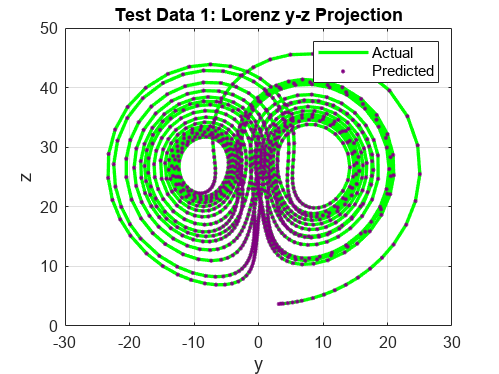

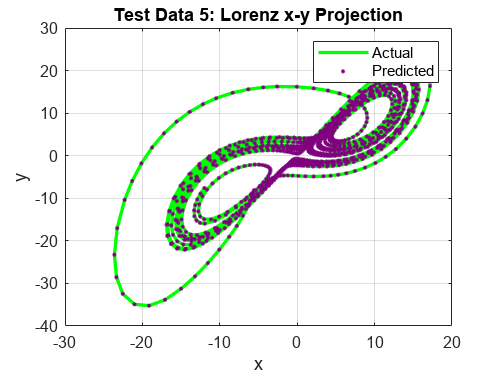

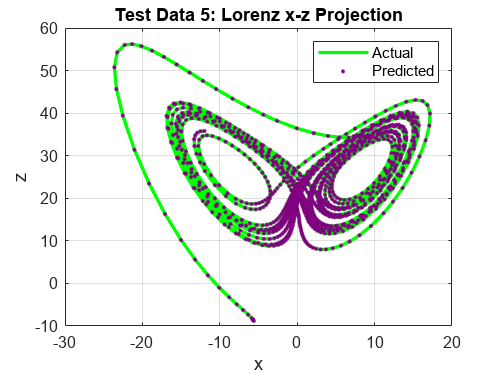

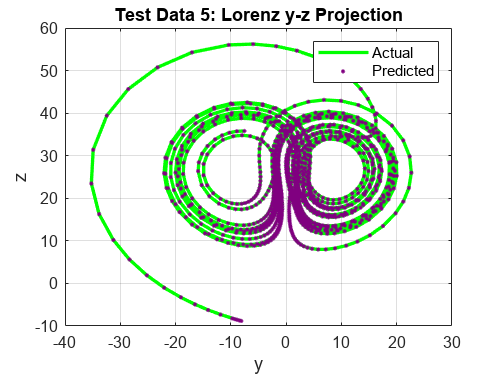

for i = [1 5]%start:numSimulations
    % Extracting actual data for the current simulation
    timeLorenz = test_data_lorenz{i, 1};
    xLorenz = test_data_lorenz{i, 2};
    yLorenz = test_data_lorenz{i, 3};
    zLorenz = test_data_lorenz{i, 4};

    % Transposing the data
    inputTimeLorenz = timeLorenz';
    inputXLorenz = xLorenz';
    inputYLorenz = yLorenz';
    inputZLorenz = zLorenz';

    
    % Making predictions using the neural network
    predictedTimeLorenz = predict(netLorenz, {inputTimeLorenz});
    predictedXLorenz = predict(netLorenz, {inputXLorenz});
    predictedYLorenz = predict(netLorenz, {inputYLorenz});
    predictedZLorenz = predict(netLorenz, {inputZLorenz});

     % Converting predicted values to matrices
    newPredictedTimeLorenz = cell2mat(predictedTimeLorenz);
    newPredictedXLorenz = cell2mat(predictedXLorenz);
    newPredictedYLorenz = cell2mat(predictedYLorenz);
    newPredictedZLorenz = cell2mat(predictedZLorenz);

     % Plotting the actual and predicted X-Y projections
    figure;
    plot(xLorenz, yLorenz, 'Color', [0, 1, 0], 'LineWidth', 2);  
    hold on;
    plot(newPredictedXLorenz, newPredictedYLorenz, 'Color', [0.5, 0, 0.5], 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 7);  
    xlabel('x');
    ylabel('y');
    title(['Test Data ', num2str(i), ': Lorenz x-y Projection']);
    legend('Actual', 'Predicted');
    grid on;
    hold off;
    % Store the current figure handle
    figHandles_xy_Projection{i} = gcf;


     % Plotting actual and predicted X-Z projections
    figure;
    plot(xLorenz, zLorenz, 'Color', [0, 1, 0], 'LineWidth', 2);  
    hold on;
    plot(newPredictedXLorenz, newPredictedZLorenz, 'Color', [0.5, 0, 0.5], 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 7);  
    xlabel('x');
    ylabel('z');
    title(['Test Data ', num2str(i), ': Lorenz x-z Projection']);
    legend('Actual', 'Predicted');
    grid on;
    hold off;
    % Store the current figure handle
    figHandles_xz_Projection{i} = gcf;


     % Plotting actual and predicted Y-Z projections
    figure;
    plot(yLorenz, zLorenz, 'Color', [0, 1, 0], 'LineWidth',2);  
    hold on;
    plot(newPredictedYLorenz, newPredictedZLorenz, 'Color', [0.5, 0, 0.5], 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 7);  
    xlabel('y');
    ylabel('z');
    title(['Test Data ', num2str(i), ': Lorenz y-z Projection']);
    legend('Actual', 'Predicted');
    grid on;
    hold off;

    % Storing the current figure handle
    figHandles_yz_Projection{i} = gcf;
end

% Saving all figures into a single MAT-file
save('L_Trajectory_figures.mat', 'figHandles_xy_Projection','figHandles_xz_Projection','figHandles_yz_Projection');

% To load the figures later:
% 1. Loading the MAT-file
loadedData = load('L_Trajectory_figures.mat');

% 2. Access the figure handles
loadedFigHandles_xy_Projection = loadedData.figHandles_xy_Projection;
loadedFigHandles_xz_Projection = loadedData.figHandles_xz_Projection;
loadedFigHandles_yz_Projection = loadedData.figHandles_yz_Projection;

% 3. Display the figures
for i = [1 5]%start:numSimulations
    figure(loadedFigHandles_xy_Projection{i});
    figure(loadedFigHandles_xz_Projection{i});
    figure(loadedFigHandles_yz_Projection{i});
end